# 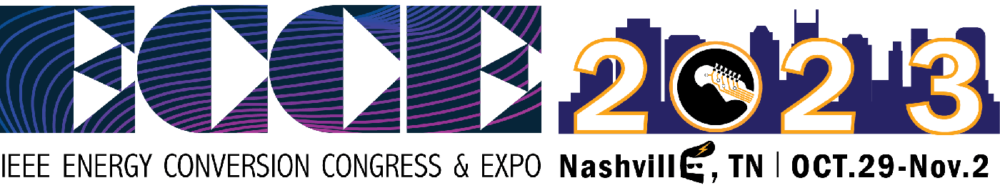

# Artificial Neural Network for Power Electronics 

***ECCE 2023***

Tutorial: **Artificial Neural Networks for Power Electronics – A Hands-On Approach**

**Demo 2 **- The goal is to use an artificial neural network for Power Electronics diagnostics: identify inverter in the failure mode. 

**Load Variables used in the Simulink Model **

clc
% clear

%% Load Variables used in the Simulink Model 
Vdc1= 35;
Vdc2= 35;
Vdc3= 35;
Vdc4= 35;
Vdc5= 35;
%Load the firing inverter angles (given)
GA_th_2 = [58 49 25 17 13];

%Set the operation default as no Fault in any inverter
Fault_Inv = 0;
SW = 0;
%%

**Open the simulink model **

uiopen('ECCE_tutorial_demo2_part1_v2.slx',1)

**Simulink Model run to get the data for the NN**

% To aquire the data from the simulink model
clear X_fT k
Fault_Inv = 0;
SW =1;
for k=1:1:6
    sim('ECCE_tutorial_demo2_part1_v2.slx')
    Fault_Inv
    X_fT(:,k)= [Vd_f ;Vq_f]
    Fault_Inv = k;
end

Fault_Inv = 0

X_fT =    -7.0180
 -178.6196


Fault_Inv = 1

X_fT =    -7.0180   -6.7895
 -178.6196 -172.8033


Fault_Inv = 2

X_fT =    -7.0180   -6.7895   -6.7340
 -178.6196 -172.8033 -171.3901


Fault_Inv = 3

X_fT =    -7.0180   -6.7895   -6.7340   -6.6194
 -178.6196 -172.8033 -171.3901 -168.4741


Fault_Inv = 4

X_fT =    -7.0180   -6.7895   -6.7340   -6.6194   -6.6000
 -178.6196 -172.8033 -171.3901 -168.4741 -167.9800


Fault_Inv = 5

X_fT =    -7.0180   -6.7895   -6.7340   -6.6194   -6.6000   -6.5927
 -178.6196 -172.8033 -171.3901 -168.4741 -167.9800 -167.7955


Fault_Inv=0;
% 

**Data Plot**

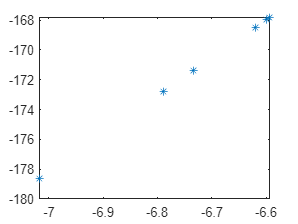

plot(X_fT(1,:),X_fT(2,:),'*');

**Normalization**

%Store the min and max values for normalization in simulink
Vmin = min(X_fT');
Vmax = max(X_fT');
Vd_min = Vmin(1);
Vq_min = Vmin(2);
Vd_max = Vmax(1);
Vq_max = Vmax(2);

X_fTN = [normalize(X_fT(1,:),'range');normalize(X_fT(2,:),'range')];

**Perceptron Neural Network**

%Create the network
clear net
net = perceptron

net =

    Neural Network
 
              name: 'Perceptron'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: true
      


%set the normalize vector as input
X=X_fTN;

**Create the target for the Neural Net**

%Create the output vector (target of the NN)

T= [0 0 0 0 0 1; 0 0 0 0 1 1; 0 0 0 1 1 1; 0 0 1 1 1 1; 0 1 1 1 1 1; 1 1 1 1 1 1]

T =      0     0     0     0     0     1
     0     0     0     0     1     1
     0     0     0     1     1     1
     0     0     1     1     1     1
     0     1     1     1     1     1
     1     1     1     1     1     1


**Configure and Train the NN**

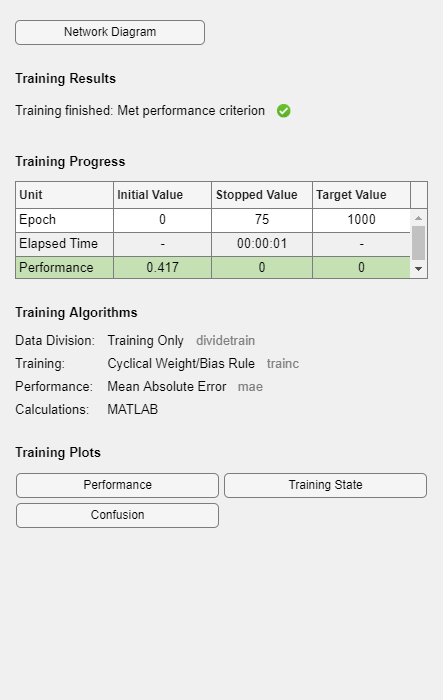

%Configure and train the NN (perceptron)
net= configure(net,X,T);

net = train(net,X,T);

net(X)

ans =      0     0     0     0     0     1
     0     0     0     0     1     1
     0     0     0     1     1     1
     0     0     1     1     1     1
     0     1     1     1     1     1
     1     1     1     1     1     1


**Generate the Simulink model of the trained NN**

%Generate the Simulink model of the NN
gensim(net,-1)

ans = 'untitled1'

**Open ECCE_tutorial_demo2_part2_v2.slx**

uiopen('ECCE_tutorial_demo2_part2_v2.slx',1)

Copy and paste the generate model of the NN in the file: *ECCE_tutorial_demo2_part2_v2.slx*

Run the simulation changing the inverter in failure mode